# Schwellwertbasierte Segmentierung

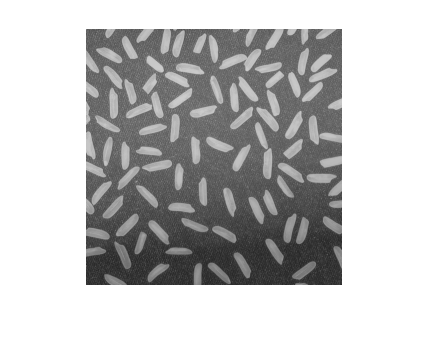

mI = imread('rice.png');
imshow(mI)

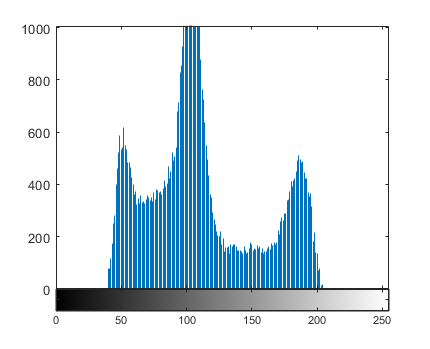

imhist(mI)

Schwellwert setzen:

Nach der SChwellweroperation erhält man ein Binärbild. Jedes Pixel beinhaltet die Information ob es zum Vorder- oder Hintergrund gehört. An dieser Stelle wurden allerdings noch keine Objekte(Reiskörner) gefunden/identifiziert

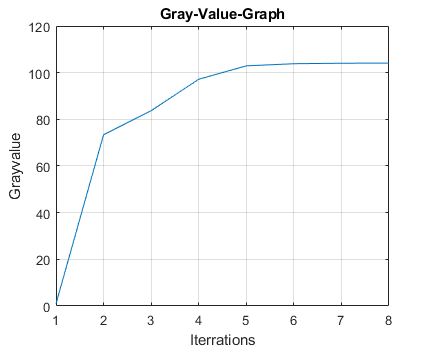

%T = 150;
%mT = mI > T; %Schwellwertoperation
minArea = 20*8;
maxArea = 300;

fun = @(block_struct) calcIterativeThreshold(block_struct.data);
mT = blockproc(mI, [55, 55], fun);

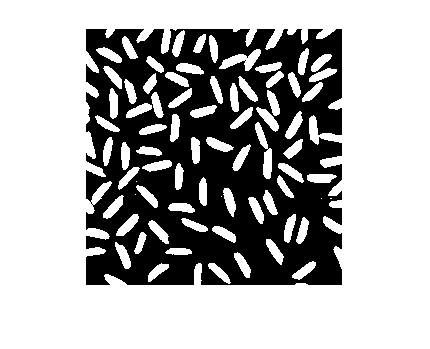


%level = graythresh(mI);
%mT = imbinarize(mI, level);
imshow(mT)

Bereinigung des Segmentierungsergebnisses

Entfernen aller Redionen die den Bildrand berühren da diese Objekte mit hoher Wahrscheinlichkeit im Bild unvollständig erfasst wurden

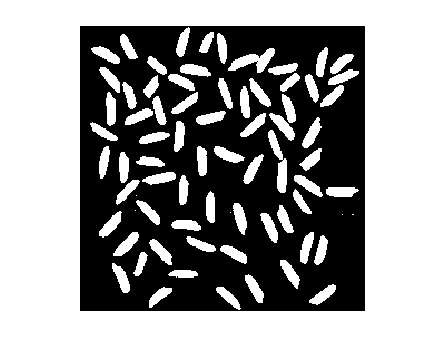

mT = imclearborder(mT);
imshow(mT)

Entfernen von Regionen deren Pixelanzahl kleiner als ein vorgegebener Wert ist

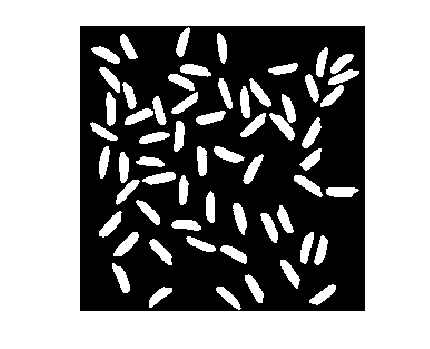

% mT = bwareaopen(mT, minArea, 4);
mT = bwpropfilt(mT, 'Area', [minArea maxArea]);
mT = bwfill(mT, 'holes');
imshow(mT)

Label-image erzeugen

Vordergrundpixel werden zu zusammenhängenden Regionen zusammengefasst. Die einzelnen Regionen werden aufsteigend nummeriert. Alle Pixel innnerhalb einer Region bekommen den selben Index (Integer). Das Resultat ähnelt einem "Grauwertbild"

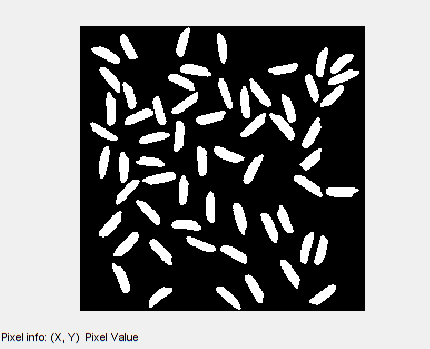

mT = bwlabel(mT, 8);
imshow(mT), impixelinfo

Falschfarbendarstellung

Jeder Region wird einen einheitliche RGB-Farge zugeordnet (bei bedarf zufällig). Solche Bilder werden zur Verarbeitung nicht weiter verwendet sondern dienen ausschließlich zur Darstellung

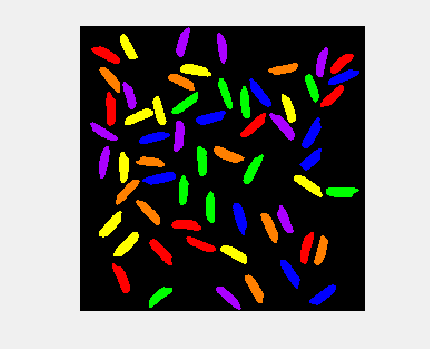

mI_rgb = label2rgb(mT, 'prism', 'k', 'shuffle');
imshow(mI_rgb)

Analyse des Label-Images

Zur Analyse des Label-Images müssen Merkmale der Regionen berechnet werden, z.B. Fläche, Umfang, Helligkeit, etc.

vsProps = regionprops(mT, 'Area', 'MajorAxisLength', 'Orientation');

vOrientation = [vsProps.Orientation];
vArea = [vsProps.Area];
vMajor = [vsProps.MajorAxisLength];

vMajor_mean = mean(vMajor)

vMajor_mean = 29.3649

vArea_mean = mean(vArea)

vArea_mean = 201.9500

vOrientation_mean = mean(vOrientation)

vOrientation_mean = -10.7282

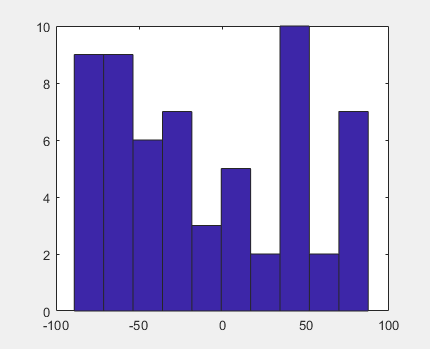


hist(vOrientation); 

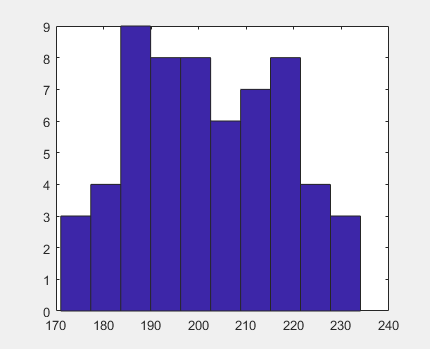

hist(vArea);

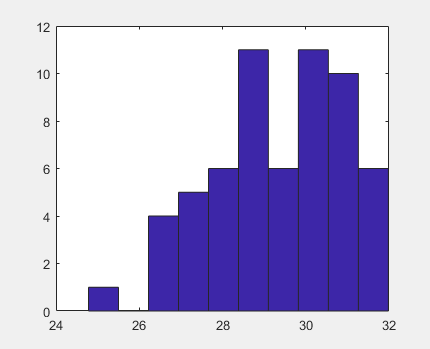

hist(vMajor);